# Clear past plots, variables and commands

close all; clear all; clc;

% Load data
load 'EE5114_CA1.mat';

% acx = x-axis accelerometer reading
% acy = y-axis accelerometer reading
% acz = z-axis accelerometer reading
%
% phi = Roll angle computed by the drone's on-board computer
% tht = Pitch angle computed by the drone's on-board computer
% psi = Yaw angle computed by the drone's on-board computer
%
% fix = GPS position fix signal
% eph = GPS horizontal variance
% epv = GPS vertical variance
% lat = GPS Latitude
% lon = GPS Longitude
% alt = GPS altitude
% gps_nSat = Number of GPS satellites
%
% out1 = Motor 1 signal
% out2 = Motor 2 signal
% out3 = Motor 3 signal
% out4 = Motor 4 signal

## Accelerometer plot

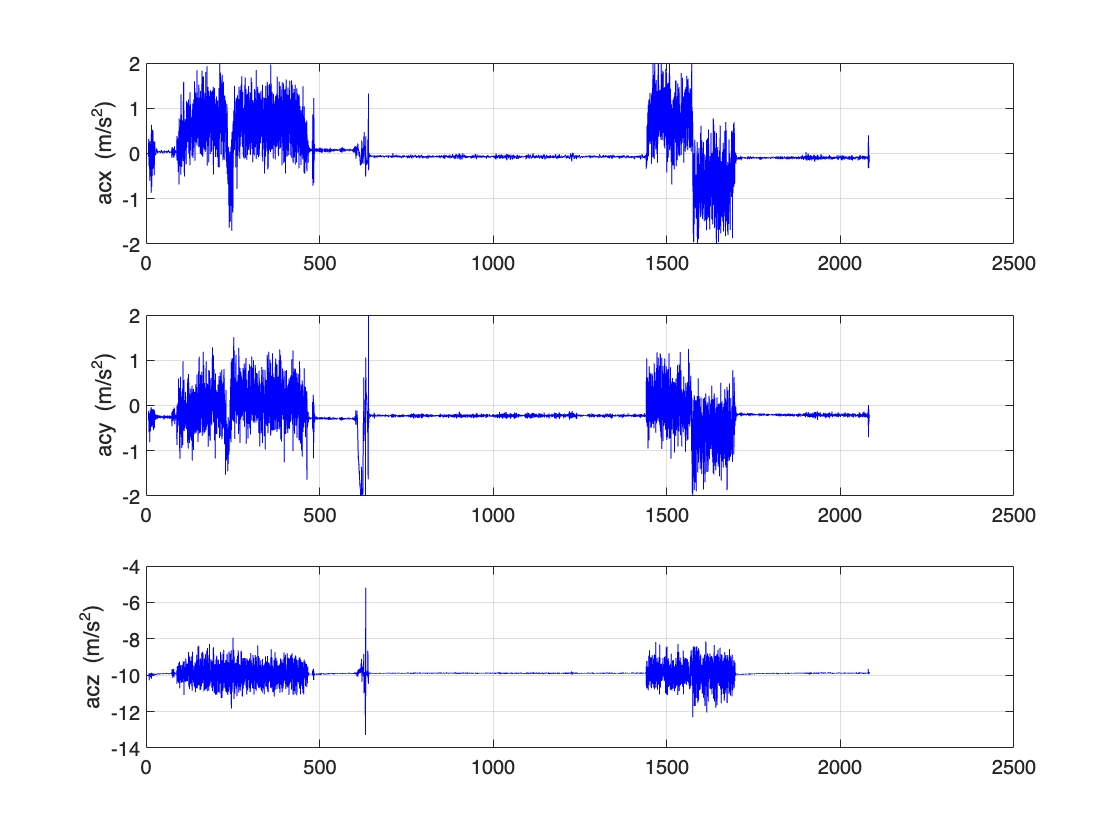

figure; set(gcf,'numbertitle','off','name','Acceleration');
subplot(3,1,1); plot(t, acx, 'b'); ylim([-2 2]); ylabel('acx (m/s^2)'); grid on;
subplot(3,1,2); plot(t, acy, 'b'); ylim([-2 2]); ylabel('acy (m/s^2)'); grid on;
subplot(3,1,3); plot(t, acz, 'b'); ylabel('acz (m/s^2)'); grid on;

## Euler angles plot

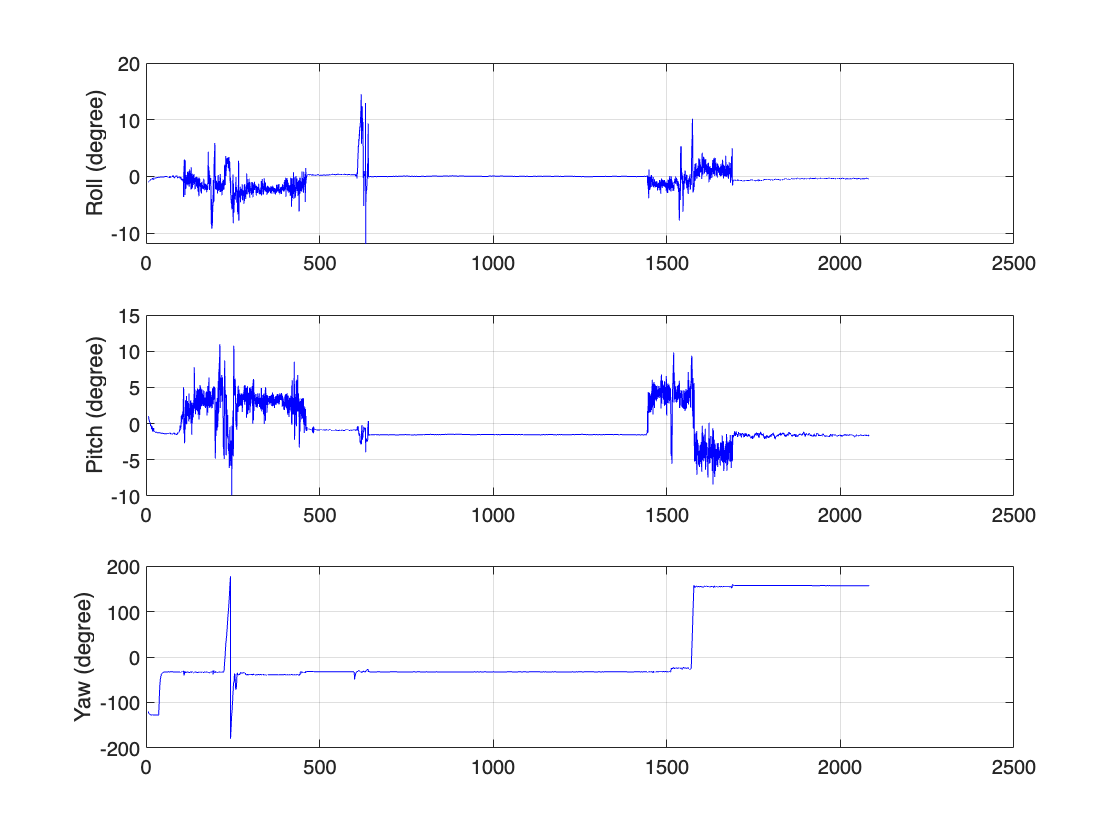

figure; set(gcf,'numbertitle','off','name','Euler Angles');
subplot(3,1,1); plot(t, rad2deg(phi), 'b'); ylabel('Roll (degree)'); grid on;
subplot(3,1,2); plot(t, rad2deg(tht), 'b'); ylabel('Pitch (degree)'); grid on;
subplot(3,1,3); plot(t, rad2deg(psi), 'b'); ylabel('Yaw (degree)'); grid on;

## GPS plot

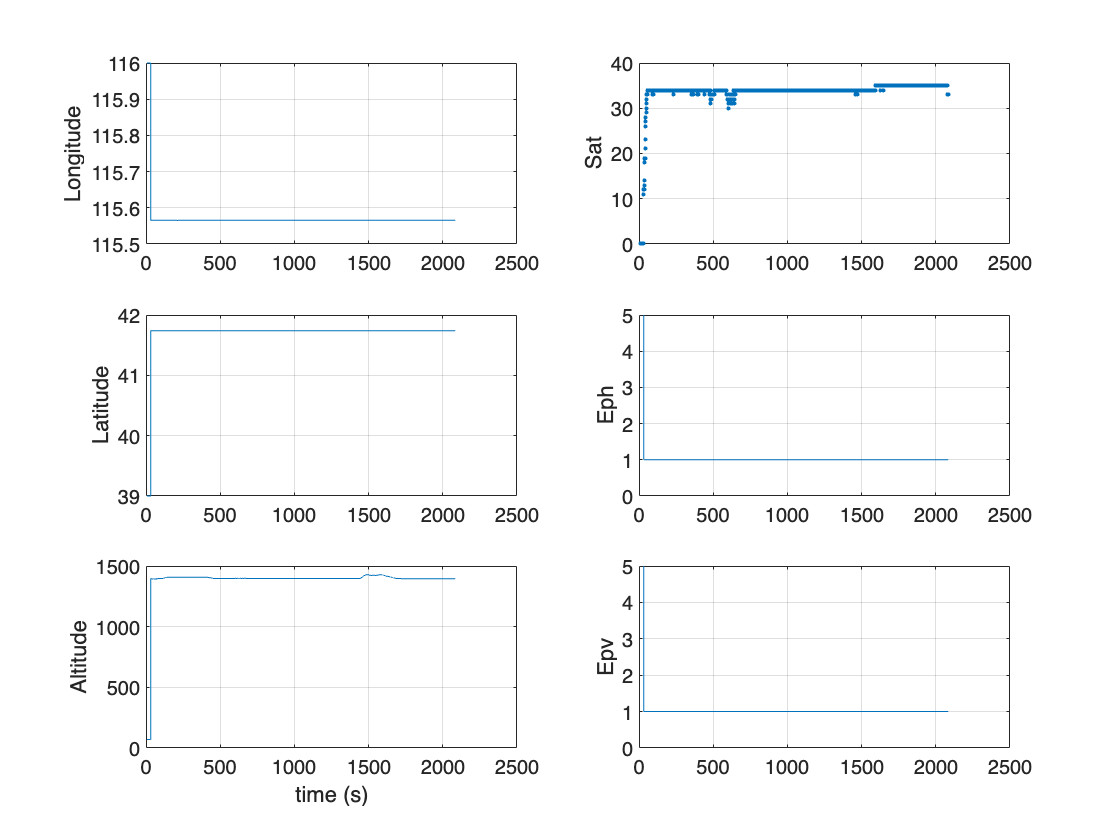

figure; set(gcf,'numbertitle','off','name','GPS');
subplot(3,2,1); plot(t, lon); ylabel('Longitude'); grid on;
subplot(3,2,3); plot(t, lat); ylabel('Latitude'); grid on;
subplot(3,2,5); plot(t, alt); ylabel('Altitude'); grid on; xlabel('time (s)');

subplot(3,2,2); plot(t, gps_nSat, '.'); ylabel('Sat'); grid on;
subplot(3,2,4); plot(t, eph); ylabel('Eph'); grid on; ylim([0 5]);
subplot(3,2,6); plot(t, epv); ylabel('Epv'); grid on; ylim([0 5]);

## Motor signal plot

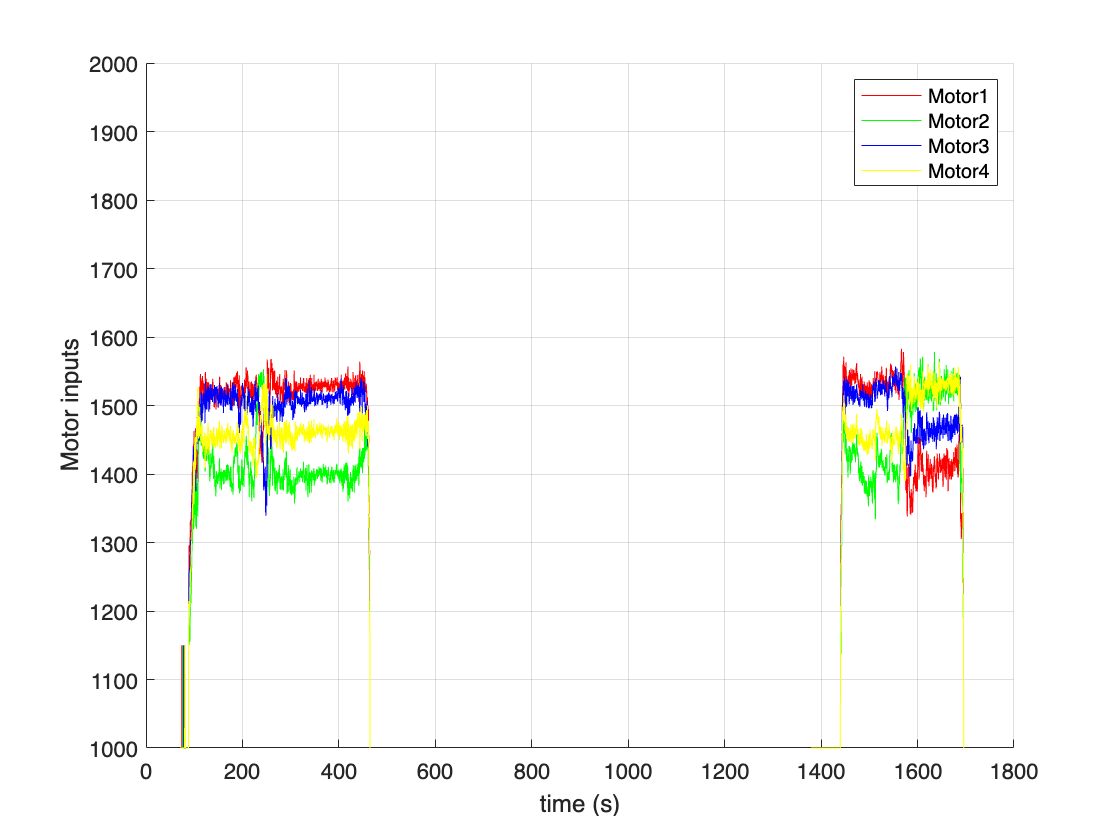

figure; set(gcf,'numbertitle','off','name','Motor Signal');
hold on;
plot(t,out1,'r');
plot(t,out2,'g');
plot(t,out3,'b');
plot(t,out4,'y');
legend('Motor1','Motor2','Motor3','Motor4');
ylabel('Motor inputs'); xlabel('time (s)'); ylim([1000 2000]); grid on;


%%%%%%%%%%%%%%%%%%%%%% Your own coding work start from here %%%%%%%%%%%%%%%%%%%%%%%%%

## Convert GPS raw measurements to local NED position values

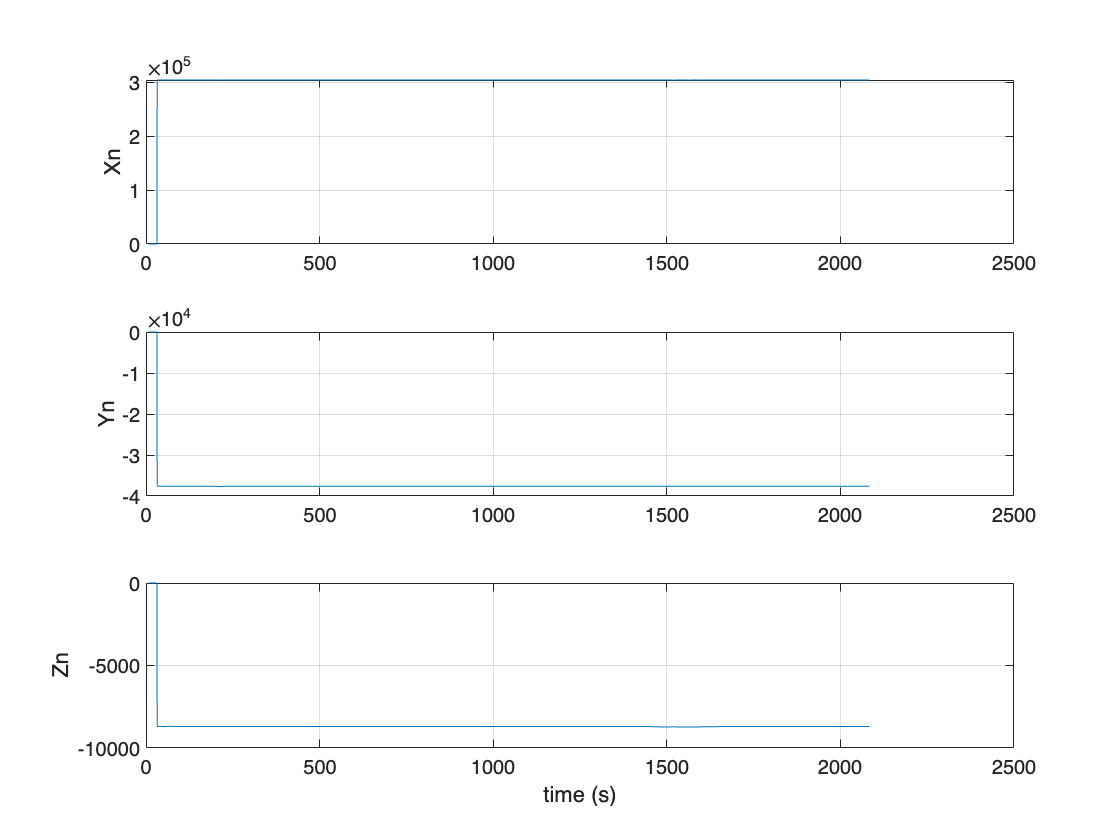

a = 6378137; %Equatorial radius
b = 6356752; %Polar radius
N = a^2./sqrt(a^2*cosd(lat).^2+b^2*sind(lat).^2);
% Calculate ECEF
Xe = (N+alt).*cosd(lat).*cosd(lon);
Ye = (N+alt).*cosd(lat).*sind(lon);
Ze = ((b^2/a^2)*N+alt).*sind(lat);
%Calculate NED
Xn = -sind(lat).*cosd(lon).*(Xe-Xe(1))-sind(lat).*sind(lon).*(Ye-Ye(1))+cosd(lat).*(Ze-Ze(1));
Yn = -sind(lon).*(Xe-Xe(1))+cosd(lon).*(Ye-Ye(1));
Zn = -cosd(lat).*cosd(lon).*(Xe-Xe(1))-cosd(lat).*sind(lon).*(Ye-Ye(1))-sind(lat).*(Ze-Ze(1));
%plot
figure; set(gcf,'numbertitle','off','name','NED');  
subplot(3,1,1); plot(t, Xn); ylabel('Xn'); grid on;
subplot(3,1,2); plot(t, Yn); ylabel('Yn'); grid on;
subplot(3,1,3); plot(t, Zn); ylabel('Zn'); grid on; xlabel('time (s)');

## Implement EKF to estimate NED position and velocity

%time t_min = 1445.66-10*60 = 845.66,对应t(4127), t_max = 1716.63+5*60=2016.63,对应t(9888);
t_min = 4127;
t_max = 9888;
num_iterations = t_max-t_min;
count = 5;%GPS update count
% Initialize state variables
x = [Xn(t_min);Yn(t_min);Zn(t_min);0;0;0;0;0;0];%[x,y,z,vx,vy,vz,bx,by,bz]
% P = eye(9);
P = diag([1, 1, 1, 1, 1, 1, 1, 1, 1]);

% Process noise and measurement noise covariances
R = diag([1, 1, 1]);% % Measurement noise covariance, according to the eph and epv

% Initialize arrays to store results
est_states = zeros(9, num_iterations);
measured_states = zeros(9, num_iterations);

%EKF
for k = t_min:t_max

    dt = t(k,1)-t(k-1,1);
    %F matrix
    f1 = [1, 0, 0, dt, 0, 0, -dt^2/2, 0, 0;
         0, 1, 0, 0, dt, 0, 0, -dt^2/2, 0;
         0, 0, 1, 0, 0, dt, 0, 0, -dt^2/2;
         0, 0, 0, 1, 0, 0, -dt, 0, 0;
         0, 0, 0, 0, 1, 0, 0, -dt, 0;
         0, 0, 0, 0, 0, 1, 0, 0, -dt];
    
    f2 = [1, 0, 0, 0, 0, 0, 0, 0, 0;
         0, 1, 0, 0, 0, 0, 0, 0, 0;
         0, 0, 1, 0, 0, 0, 0, 0, 0;
         0, 0, 0, 1, 0, 0, 0, 0, 0;
         0, 0, 0, 0, 1, 0, 0, 0, 0;
         0, 0, 0, 0, 0, 1, 0, 0, 0;
         0, 0, 0, 0, 0, 0, cos(psi(k))*cos(tht(k)),cos(psi(k))*sin(tht(k))*sin(phi(k))-sin(psi(k))*cos(phi(k)),cos(psi(k))*sin(tht(k))*cos(phi(k))+sin(psi(k))*sin(phi(k));
         0, 0, 0, 0, 0, 0, sin(psi(k))*cos(tht(k)),sin(psi(k))*sin(tht(k))*sin(phi(k))+cos(psi(k))*cos(phi(k)),sin(psi(k))*sin(tht(k))*cos(phi(k))-cos(psi(k))*sin(phi(k));
         0, 0, 0, 0, 0, 0, -sin(tht(k)),cos(tht(k))*sin(phi(k)),cos(tht(k))*cos(phi(k))];
    
    f3 = [0, 0, 0, 0, 0, 0, 1, 0, 0;
         0, 0, 0, 0, 0, 0, 0, 1, 0;
         0, 0, 0, 0, 0, 0, 0, 0, 1];
    
    F = [f1*f2;f3];

    %G matrix
    g1 = [dt^2/2,0,0;
        0,dt^2/2,0;
        0,0,dt^2/2;
        dt,0,0;
        0,dt,0;
        0,0,dt;
        0,0,0;
        0,0,0;
        0,0,0];
    
    g2 = [cos(psi(k))*cos(tht(k)),cos(psi(k))*sin(tht(k))*sin(phi(k))-sin(psi(k))*cos(phi(k)),cos(psi(k))*sin(tht(k))*cos(phi(k))+sin(psi(k))*sin(phi(k)),0;
         sin(psi(k))*cos(tht(k)),sin(psi(k))*sin(tht(k))*sin(phi(k))+cos(psi(k))*cos(phi(k)),sin(psi(k))*sin(tht(k))*cos(phi(k))-cos(psi(k))*sin(phi(k)),0;
         -sin(tht(k)),cos(tht(k))*sin(phi(k)),cos(tht(k))*cos(phi(k)),9.81];
    
    G = g1*g2;

    % Process noise covariance Q
    qxyz = [1,0,0,0;
            0,1,0,0;
            0,0,1,0;
            0,0,0,0];
    
    Q = G*qxyz*G';


    % Prediction step

    % accelerate = [acx(k)+x(7);acy(k)+x(8);acz(k)+x(9);1];
    accelerate = [acx(k);acy(k);acz(k);1];
    x_pred = F*x+G*accelerate;
    P_pred = F*P*(F')+Q;

    %Correction step
    if count == 5
        count = 1; %reset count
        y = [Xn(k);Yn(k);Zn(k)];

        H = [1, 0, 0, 0, 0, 0, 0, 0, 0;
             0, 1, 0, 0, 0, 0, 0, 0, 0;
             0, 0, 1, 0, 0, 0, 0, 0, 0];
    
        K = P_pred*(H')*inv(H*P_pred*(H')+R);
        % y = [Xn(k);Yn(k);Zn(k)]; 
        x = x_pred+K*(y - H*x_pred);
        P = (eye(9) - K * H) * P_pred;
    else
        count = count+1;
    end
    % Store results
    est_states(:, k-(t_min-1)) = x;
    measured_states(:,k-(t_min-1)) = [Xn(k);Yn(k);Zn(k); 0; 0; 0; 0; 0; 0];

end

## NED position plots

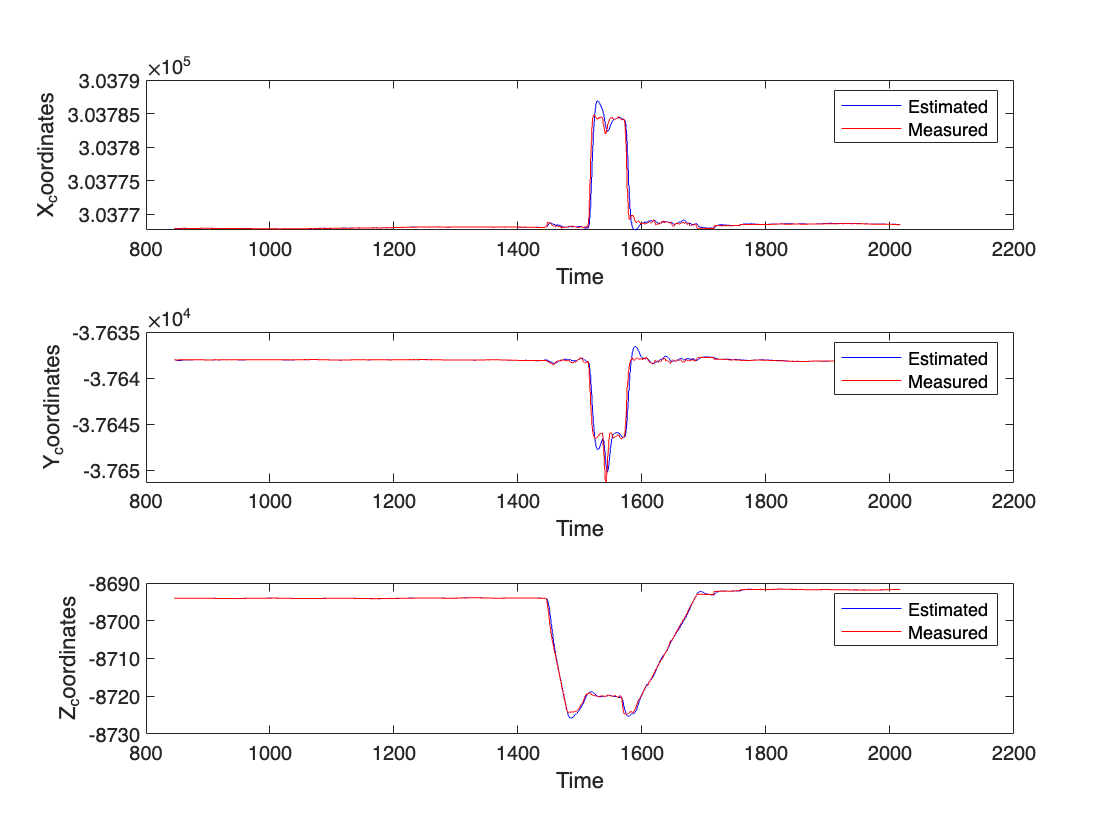

% Plot results
time_steps = t(t_min:t_max);

figure;
subplot(3,1,1);
plot(time_steps, est_states(1,:), 'b', time_steps, measured_states(1,:), 'r');
xlabel('Time');
ylabel('X_coordinates');
legend('Estimated', 'Measured');

subplot(3,1,2);
plot(time_steps, est_states(2,:), 'b', time_steps, measured_states(2,:), 'r');
xlabel('Time');
ylabel('Y_coordinates');
legend('Estimated', 'Measured');

subplot(3,1,3);
plot(time_steps, est_states(3,:), 'b', time_steps, measured_states(3,:), 'r');
xlabel('Time');
ylabel('Z_coordinates');
legend('Estimated', 'Measured');

## NED velocities plots

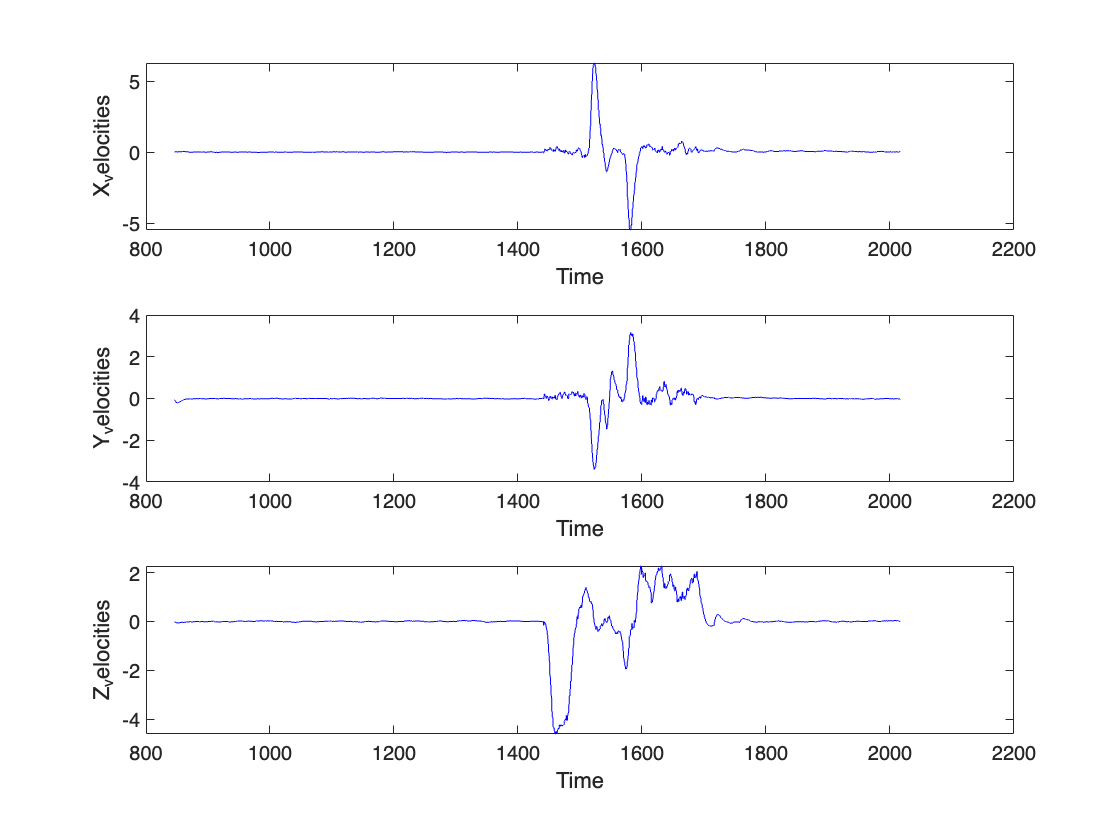

figure;
subplot(3,1,1);
plot(time_steps, est_states(4,:), 'b');
xlabel('Time');
ylabel('X_velocities');

subplot(3,1,2);
plot(time_steps, est_states(5,:), 'b');
xlabel('Time');
ylabel('Y_velocities');

subplot(3,1,3);
plot(time_steps, est_states(6,:), 'b');
xlabel('Time');
ylabel('Z_velocities');

test